close all;
clear variables;

% % пример использования номер 1 - ВЕРНОЕ
% X_comp = [1,2,3,4];
% Z_comp = [5,6,7,8];
% X_ref = [1,2,3,4];
% Z_ref = [5,6,7,8];
% 
% I_compare = [1,2,3,4];
% I_ref = [4,3,2,1];
% 
% de_I = Compare_current(I_compare, I_ref, X_comp, Z_comp, X_ref, Z_ref)
% de_I == [9,1,1,9]

% % пример использования номер 2 - ВЕРНОЕ 
% X_comp = [1,2,3,4];
% Z_comp = [5,6,7,8];
% X_ref = [1,2,3,4];
% Z_ref = [5,6,7,8];
% 
% I_compare = [1+1i,2+2i,3+3i,-4-4i];
% I_ref = [4+1i,3,2,1];
% 
% de_I = Compare_current(I_compare, I_ref, X_comp, Z_comp, X_ref, Z_ref)
% round(de_I,3) == [9,5,10,41]

% % пример использования номер 3 - НЕВЕРНОЕ 
% X_comp = [1,2,3,4,0];
% Z_comp = [5,6,7,8,0];
% X_ref = [1,2,3,4];
% Z_ref = [5,6,7,8];
% 
% I_compare = [1+1i,2+2i,3+3i,-4-4i,1];
% I_ref = [4+1i,3,2,1];
% 
% de_I = Compare_current(I_compare, I_ref, X_comp, Z_comp, X_ref, Z_ref)
% round(de_I,3) == [9,5,10,41]

% % пример использования номер 3 - НЕВЕРНОЕ  
% X_comp = [1,2,3,4,0,1];
% Z_comp = [5,6,7,8,0,1];
% X_ref = [1,2,3,4];
% Z_ref = [5,6,7,8];
% 
% I_compare = [1+1i,2+2i,3+3i,-4-4i,1,2];
% I_ref = [4+1i,3,2,1];
% 
% de_I = Compare_current(I_compare, I_ref, X_comp, Z_comp, X_ref, Z_ref)
% round(de_I,3) == [9,5,10,41]

% % скачаем необходимые данные 
% I_comp = load("MFIE_Hpol", "I").I;
% 
% I_ref = load("MAS_H_pol", "I_real").I_real;
% X_ref = load("MAS_H_pol", "xAS").xAS;
% Z_ref = load("MAS_H_pol", "zAS").zAS;

% N_comp = 1
% 
% de_I = Compare_current_v2(I_ref, X_ref, Z_ref, N_comp, I_comp)
% 
% figure;
% plot(1:length(de_I), de_I,'r-');
% title('Разница в токах H\_pol, elips'); 
% xlabel('Номер участка'); 
% ylabel('Разница');

Задаем параметры эллипса и падающей волны 

a = 2; 
b = 1;
phi_grad = 60; 

Предположим мы получили невязку *** для МВИ источников и выбрали количество источник N_mas_ref

N_mas_ref = 400;

Выбираем количество участков разибения N_comp для МИУ для 1-го графика 

N_comp = 400;

Генерируем N_comp точки на элипсе X_comp, Z_comp.

% x(i), z(i), dx(i),tx,tz,nx,nz, x_midle, z_midle

% Сгенерируем параметры элипса и упакуем их в структуру
S = generate_elips_point(a,b,N_comp)

S = struct with fields:
                    x: [1×400 double]
                    z: [1×400 double]
                   dx: [1×400 double]
              x_midle: [1×400 double]
              z_midle: [1×400 double]
                   tx: [1×400 double]
                   tz: [1×400 double]
                   nx: [1×400 double]
                   nz: [1×400 double]
                    a: 2
                    b: 1
    phi_for_graf_real: [1×400 double]


Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МВИ и получем токи I_ref (длиной N_comp)

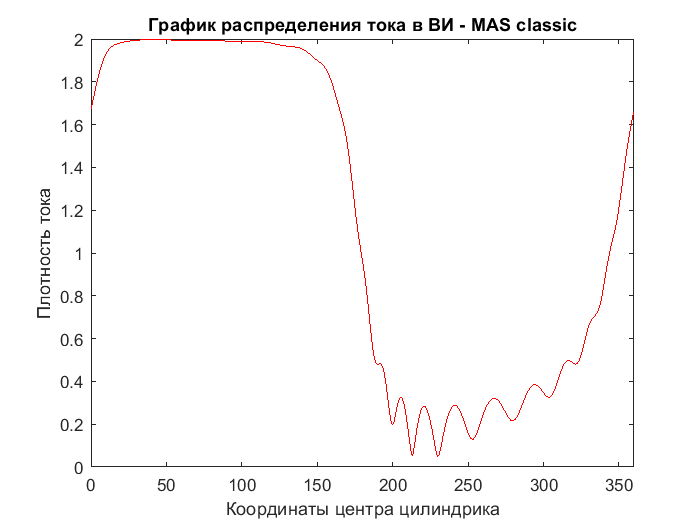

I_ref =    1.6504 - 0.2859i
   1.6356 - 0.4278i
   1.6093 - 0.5662i
   1.5724 - 0.7003i
   1.5257 - 0.8292i
   1.4700 - 0.9521i
   1.4062 - 1.0685i
   1.3353 - 1.1778i
   1.2581 - 1.2797i
   1.1757 - 1.3739i


I_ref = MAS_elips_clasic(N_mas_ref, N_comp, S, phi_grad)

Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МИУ и получем токи I_comp (длиной N_comp)

Напомним что количество источников N_mas_ref, а количество точек на основном элипсе N_сomp

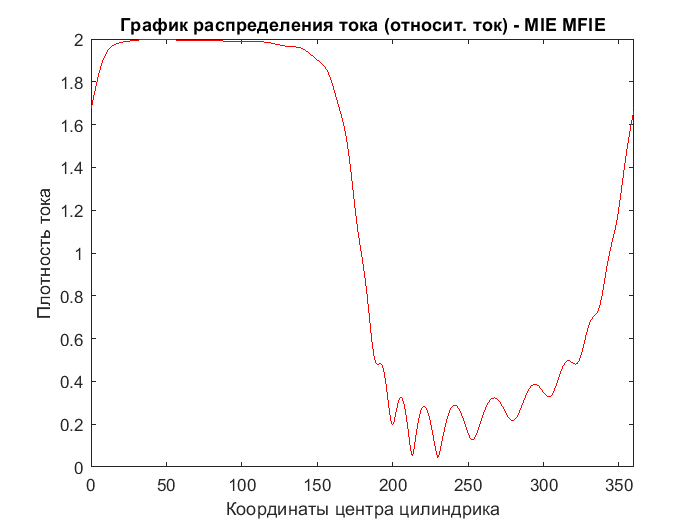

I_comp =   -1.6553 + 0.2865i
  -1.6378 + 0.4283i
  -1.6115 + 0.5670i
  -1.5746 + 0.7013i
  -1.5277 + 0.8304i
  -1.4719 + 0.9534i
  -1.4080 + 1.0700i
  -1.3369 + 1.1794i
  -1.2596 + 1.2815i
  -1.1770 + 1.3758i


I_comp = MFIE_MIE_H_pol_elips(N_comp, S, phi_grad)

Сравниваем токи и записываем в график 

de_I = abs(I_ref + I_comp)

de_I =     0.0050
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023
    0.0023


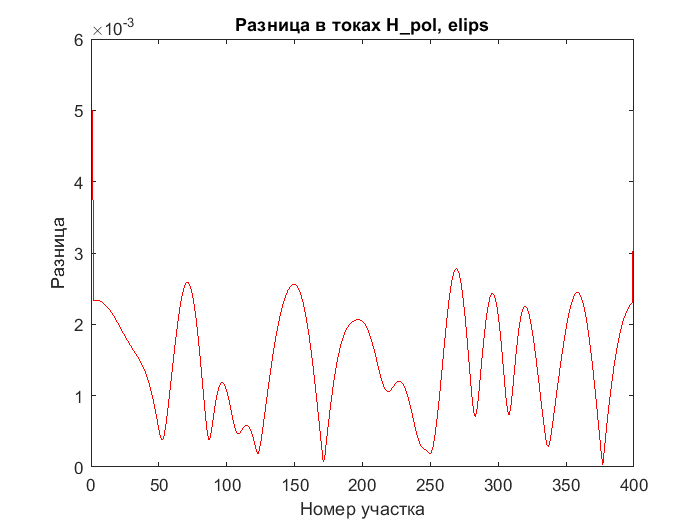


figure;
plot(1:length(de_I), de_I,'r-');
title('Разница в токах H\_pol, elips'); 
xlabel('Номер участка'); 
ylabel('Разница');

## 1) Структура для генерации точек элипса 

function[S] = generate_elips_point(a,b,N)

Входные параметры

    delta_phi = 360/N;

Генерация точек

    delta_phi = 360/N;
    x = zeros(1,N);
    z = zeros(1,N);
    
    for i = 1 : N
        z(i) = b*sind(delta_phi*(i-1));
        x(i) = a*cosd(delta_phi*(i-1));
    end
    

Расчет dx для каждого участка

    for i = 1 : N
        if i == N
            d_x = (x(1)-x(i));
            d_z = (z(1)-z(i));
        else
            d_x = (x(i+1)-x(i));
            d_z = (z(i+1)-z(i));
        end
        
        dx(i) = sqrt(d_x^2+d_z^2);    
    end

Посчитаем t для каждого отрезка

    for i = 1 : N
        if i == N
            tx(i) = -((x(1)-x(i)))/dx(i);
            tz(i) = -((z(1)-z(i)))/dx(i);
        else
            tx(i) = -(x(i+1)-x(i))/dx(i);
            tz(i) = -(z(i+1)-z(i))/dx(i);
        end
    end

Посчитаем n для каждого отрезка

    %   нормальный вектор найдем с помощью матрицы повороты
        alpha = -90;
        matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];
    
    for i = 1 : N
         matrix_temp = [tx(i), tz(i)]*matrix;
         nx(i) = matrix_temp(1);
         nz(i) = matrix_temp(2);
    end

Координаты центров отрезков

    for i = 1 : N 
        if i == N
            x_midle(i) = ((x(1)+x(i)))/2;
            z_midle(i) = ((z(1)+z(i)))/2;
        else
            x_midle(i) = (x(i+1)+x(i))/2;
            z_midle(i) = (z(i+1)+z(i))/2;
        end    
    end
        

Сделаем счетчик для графика в градусах

    for i = 1 : N
        z_m = z_midle(i);
        x_m = x_midle(i);
        
        if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
            phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
        else
            phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
        end
    end

%   упакуем это в струкутру 
    S = struct();
    S.x = x;
    S.z = z;
    S.dx = dx;
    S.x_midle = x_midle;
    S.z_midle = z_midle;
    S.tx = tx;
    S.tz = tz;
    S.nx = nx;
    S.nz = nz;
    S.a = a;
    S.b = b;
    S.phi_for_graf_real = phi_for_graf_real;
    
end


## 2) MIE MFIE

function[I] = MFIE_MIE_H_pol_elips(N_comp, S, phi_grad)

Входные параметры

    
    N = N_comp;
    delta_phi = 360/N;
    k = 2*pi; 
    
    % распакуем структуру 
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    nx = S.nx;
    nz = S.nz;
    x_midle = S.x_midle;
    z_midle = S.z_midle;
    

Порог

    treshold = 1*max(dx);

Дополнительные параметры

    gamma = 1.781072417990;
    delta = dx/2;

Изучим один цикл    

    for m = 1 : N
        
    %   Координаты в исходной системе координат (в ГСК) 
    % - т.к. точки находятся в центре отрезков разбиения
        xm = x_midle(m);
        zm = z_midle(m);
        txm = tx(m);
        tzm = tz(m);
        nxm = nx(m);
        nzm = nz(m);
        
        for n = 1 : N
        %   Координаты в исходной системе координат (в ГСК)
            xn = x_midle(n);
            zn = z_midle(n);
            txn = tx(n);
            tzn = tz(n);
            nxn = nx(n);
            nzn = nz(n);
    
        %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

            x_begin_O2 = xn;
            z_begin_O2 = zn;
            
        %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
            x_mO2 = xm - x_begin_O2;
            z_mO2 =  zm - z_begin_O2;
             
    %       Положим этот вектор на новую СК
    %       Координаты этой точки (в ЛСК)
            xmO2 = x_mO2*txn + z_mO2*tzn;
            zmO2 = x_mO2*nxn + z_mO2*nzn;
               

Т.к. взяли на начало середину отрезка то тут будет

            % координаты в локальных координатах
            umn = xmO2;
            wmn = zmO2;
    
    %       Растояние между m и n (в ГСК)
            xmn = xm - xn;
            zmn = zm - zn;
            r = sqrt(xmn^2 + zmn^2);
            
    %       Расчет матричных элементов (в ЛСК)
            
            Hys = 0;
         
            cur_dx = dx(n); % current dx
            
            if n == m %r < 0.001*dx 
                
                % y - cоставляющая 
                Hys = -0.5;
                
            elseif abs(n - m) < 1.5 %r <= 2*dx
                % y - cоставляющая                     
                umn_plus_dx2 = umn + cur_dx/2;
                umn_minus_dx2 = umn - cur_dx/2;
                Hys = -(1i/8*wmn*k^2*cur_dx + 1/(2*pi)*(atan(umn_plus_dx2/wmn) - atan(umn_minus_dx2/wmn)));
                     
            else 
                % y - cоставляющая
                rmn = sqrt(umn^2 + wmn^2);    
                Hys = -1i/4*k*cur_dx*(wmn/rmn*besselh(1,1,k*rmn));  
                
            end
            
    %       символ кронкера
            if m == n
                kronker = 1;
            else 
                kronker = 0;
            end
            
            % расчет матричнх элементов 
            Zmn(m,n) = kronker + Hys;
        end
    end
     

Расчет падающего поля

    for m=1:N
        nxm = nx(m);
        nzm = nz(m);
        
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        
        % Определим координаты
        xm = x_midle(m);
        zm = z_midle(m);
        
    %   Итоговое падающее поле
        Hi(m,1) = -exp(cx*xm+cz*zm); 
    end

Посчитаем токи и построим график

    % расчеток токов ВИ 
    I=Zmn\Hi;

Сделаем счетчик для графика в градусах

    % распакуем структуру 
    phi_for_graf_real = S.phi_for_graf_real;
    
    figure;
    fig = plot(phi_for_graf_real, abs(I), 'r');
    title('График распределения тока (относит. ток) - MIE MFIE'); 
    xlabel('Координаты центра цилиндрика'); 
    xlim([0 360])
    ylabel('Плотность тока');

end



## 3) MAS CLASSIC

function[I_real] = MAS_elips_clasic(N_mas_ref, N_comp, S, phi_grad)

Входные параметры

    N_comp;
    N_mas_ref;

    % распакуем структуру 
    a = S.a;
    b = S.b;

    f = sqrt(a^2 - b^2);
    a1 = 1.8;  
    b1 = sqrt(a1^2 - f^2); 

    delta_phi = 360/N_comp;
    k = 2*pi; 

Генерация точек элипса

    % распакуем структуру 
    x = S.x_midle;
    z = S.z_midle;
        

Генерация точек контура для ВИ

    for i = 1 : N_mas_ref
        xAS(i) = a1*cosd(delta_phi*(i-1));
        zAS(i) = b1*sind(delta_phi*(i-1));
    end


Касательная к основному элипсу

    % распакуем структуру 
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    nx = S.nx;
    nz = S.nz;

Изучим один цикл

    % count = 0;
    % пробегаемся по всем точкам оснвого элипса
    for m = 1 : N_comp
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
        %пробегаемся по всем точкам ВИ
        for n = 1 : N_mas_ref
            xn = xAS(n);
            zn = zAS(n);
            
            % Растояние между m и n
            dx = xm - xn;
            dz = zm - zn;
            r = sqrt(dx^2 + dz^2);
    
            Es(m,n) = besselh(1,1,k*r)*(dx*tzm - dz*txm)/r;         
            
        end
    end
     

Расчет падающего поля

    for m=1:N_comp
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        % Определим координаты
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
    %   Итоговое падающее поел - это суперпозиция полей
        Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
        Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
        Ei(m,1) = Eix*txm + Eiz*tzm;         
    end
    

Посчитаем токи и построим график

    % расчеток токов ВИ 
    I=Es\Ei;
    
    for m = 1 : N_comp
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
        %пробегаемся по всем точкам ВИ
        sum_count = 0;
        for n = 1 : N_mas_ref
            xn = xAS(n);
            zn = zAS(n);    
        
            % Растояние между m и n
            xmn = (xm - xn);
            zmn = (zm - zn);
            r = sqrt(xmn^2 + zmn^2);
            
            Hs = I(n)*besselh(0, 1, k*r);
           
            sum_count = sum_count + Hs;
        end
        
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        Hi = exp(cx*xm+cz*zm); 
       
        I_real(m,1) = sum_count + Hi;
    end

Сделаем счетчик для графика в градусах

    % распакуем структуру 
    phi_for_graf_real = S.phi_for_graf_real;
 
    figure;
    fig = plot(phi_for_graf_real, abs(I_real), 'r');
    title('График распределения тока в ВИ - MAS classic'); 
    xlabel('Координаты центра цилиндрика'); 
    xlim([0 360])
    ylabel('Плотность тока');

end

